For CSTR Pulse

clc 
clear

% reactor properties
v=1;
V =220;
tau = V/v;

% for pulse
C_pulse = [99	680	1085	1318	1385	1400	1387	1360	1331	1283	1247	1203	1164	1126	1086	1052	1026	949	915	892	857	825	794	775	745	725	700	678	654	635	596	575	557	543	523	507	494	460	447	433	420	406	395	384	372	362	350	342	332	323	315	305	297	289	282	274	267	261	255	248	243	235	226	221	217	212	201	197	194	190	186	183	181	178	175	172	169	166	163	160	158	156	153	151	149	146	145	142	140	138	137	135	134	132	130	129	128	126	125	124	122	121	120	119	118	116	113	112	110	110	108	106	106	104	103	102	100	99	98	98	97	97	97	97
]; %an array of values given by TA
time_pulse = [0	10	20	30	40	50	60	70	80	90	100	110	120	130	140	150	160	170	180	190	200	210	220	230	240	250	260	270	280	290	300	310	320	330	340	350	360	370	380	390	400	410	420	430	440	450	460	470	480	490	500	510	520	530	540	550	560	570	580	590	600	610	620	630	640	650	660	670	680	690	700	710	720	730	740	750	760	770	780	790	800	810	820	830	840	850	860	870	880	890	900	910	920	930	940	950	960	970	980	990	1000	1010	1020	1030	1040	1060	1080	1100	1120	1140	1170	1200	1230	1260	1290	1320	1360	1400	1440	1480	1520	1560	1600	1640
];% an array of corresponding time values

len = length(C_pulse);

% Resident Time Distribution
sum =0;
for i=1:len-1
    sum = sum + (time_pulse(i+1)-time_pulse(i))*(C_pulse(i+1)+C_pulse(i))/2;
end
sum

sum = 542995


E_exp = C_pulse/sum;
E_exp = E_exp';

% Theroretical Calculations
E_theo = (exp(-time_pulse/tau)/tau)';

% for t_mean
sum_t = 0;
for i = 1:len-1
sum_t = sum_t + (time_pulse(i+1)+time_pulse(i))*(time_pulse(i+1)-time_pulse(i))*(C_pulse(i+1)+C_pulse(i))/4;
end

t_mean = sum_t/sum

t_mean = 418.0183


% Variance calulation tiem 

sum_v =0;
for i = 1:len-1
sum_v = sum_v + ((time_pulse(i+1)+time_pulse(i))^2)*(time_pulse(i+1)-time_pulse(i))*(C_pulse(i+1)+C_pulse(i))/8;
end

variance = sum_v/sum - t_mean^(2)

variance = 1.6757e+05

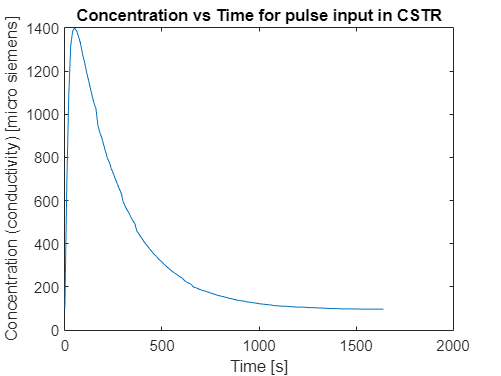



% Plotting Concentrations
plot(time_pulse,C_pulse)
xlabel("Time [s]")
ylabel("Concentration (conductivity) [micro siemens]")
title("Concentration vs Time for pulse input in CSTR")

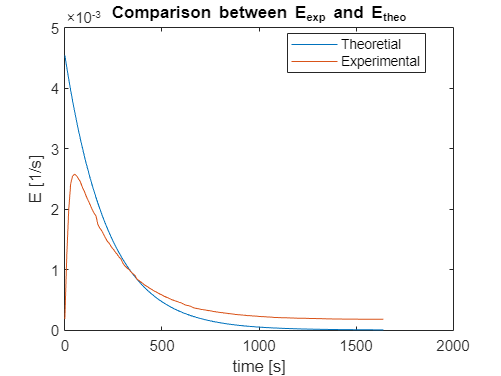


% plotting E_exp and E_theo
plot(time_pulse, E_theo)
hold on
plot(time_pulse, E_exp)
legend('Theoretial', 'Experimental', 'Location', 'best')
xlabel("time [s]")
ylabel("E [1/s]")
title("Comparison between E_{exp} and E_{theo}")
hold off

For STEP input

C_both=[96	96	96	96	96	95	95	95	96	96	96	96	96	96	95	96	96	96	96	97	97	100	107	118	135	162	187	219	258	289	326	363	398	434	469	504	536	569	603	635	662	689	719	746	777	806	828	849	876	898	921	943	966	986	1007	1031	1047	1063	1082	1101	1118	1135	1155	1167	1182	1195	1211	1225	1235	1252	1264	1276	1289	1301	1312	1324	1332	1343	1354	1363	1370	1380	1389	1397	1405	1413	1421	1428	1435	1443	1449	1455	1462	1467	1473	1479	1484	1494	1500	1504	1509	1513	1517	1521	1523	1527	1529	1533	1536	1540	1544	1550	1554	1557	1563	1568	1573	1577	1581	1585	1590	1593	1597	1601	1604	1606	1609	1612	1615	1617	1619	1621	1622	1624	1625	1628	1629	1631	1632	1633	1635
]; % value from data collected by us
C_LFR=[119	120	119	120	120	120	119	118	120	119	120	122	124	125	124	124	129	170	261	436	603	761	852	922	966	1020	1053	1084	1104	1118	1136	1142	1154	1168	1176	1190	1199	1210	1223	1229	1242	1250	1259	1269	1275	1285	1289	1299	1302	1311	1315	1323	1329	1333	1340	1346	1348	1354	1360	1363	1370	1374	1377	1379	1385	1388	1392	1393	1399	1401	1405	1408	1410	1411	1414	1417	1420	1422	1425	1428	1430	1432	1433	1434	1437	1440	1438	1440	1442	1441	1443	1445	1448	1450	1453	1450	1454	1452	1453	1455	1456	1456	1458	1459	1460	1461	1460	1462	1467	1464	1466	1465	1469	1470	1470	1471	1473	1469	1475	1473	1474	1473	1475	1476	1477	1478	1477	1479	1477	1477	1479	1479	1480	1482	1480	1482	1481	1483	1482	1482	1484
] ;% value from data collected by us
time_step = [0	10	20	30	40	50	60	70	80	90	100	110	120	130	140	150	160	170	180	190	200	210	220	230	240	250	260	270	280	290	300	310	320	330	340	350	360	370	380	390	400	410	420	430	440	450	460	470	480	490	500	510	520	530	540	550	560	570	580	590	600	610	620	630	640	650	660	670	680	690	700	710	720	730	740	750	760	770	780	790	800	810	820	830	840	850	860	870	880	890	900	910	920	930	940	950	960	970	980	990	1000	1010	1020	1030	1040	1050	1060	1080	1100	1120	1140	1160	1180	1200	1220	1240	1260	1280	1300	1320	1340	1360	1380	1400	1420	1440	1460	1480	1500	1520	1540	1570	1600	1630	1660	1690	1720	1750	1780	1810	1840
];% the time corresponding to the values,

len = length(time_step);
C_o = C_both(len);
F_exp_L = (C_LFR/C_o)';
E_exp_L = (zeros(1,len-1));
for i = 1:len-1
    E_exp_L(i) = (F_exp_L(i+1) - F_exp_L(i))/(time_step(i+1) - time_step(i));
end
E_exp_L = E_exp_L';
% for F_theo of LFR
F_theo_L = zeros(1,len);
for i = 1:len
    if time_step(i) >= tau/2
        F_theo_L(i) = 1 - (tau*tau)/(4*time_step(i)*time_step(i));
    end
end
F_theo_L=F_theo_L'

F_theo_L =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0



% For LFR + CSTR
F_exp_both = (C_both/C_o)';
E_exp_both = zeros(1,len-1);
for i = 1:len-1
    E_exp_both(i) = (F_exp_both(i+1) - F_exp_both(i))/(time_step(i+1) - time_step(i));
end
E_exp_both=E_exp_both'

E_exp_both =          0
         0
         0
         0
   -0.0001
         0
         0
    0.0001
         0
         0


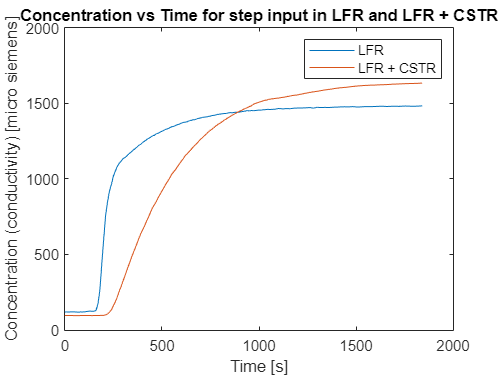


% Plotting Concentrations
plot(time_step,C_LFR)
hold on
plot(time_step,C_both)
hold off
xlabel("Time [s]")
ylabel("Concentration (conductivity) [micro siemens]")
legend("LFR", "LFR + CSTR")
title("Concentration vs Time for step input in LFR and LFR + CSTR")

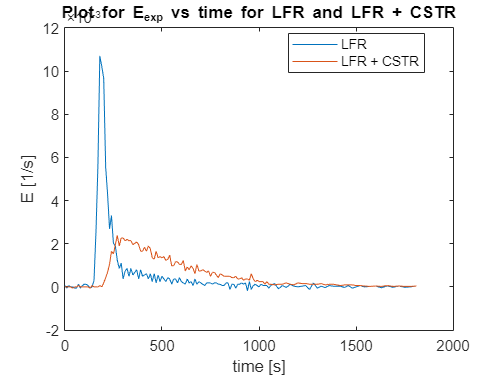


% Plotting E and F
plot(time_step(1:len-1),E_exp_L)
hold on
plot(time_step(1:len-1),E_exp_both)
hold off
legend('LFR', 'LFR + CSTR', 'Location', 'best')
xlabel("time [s]")
ylabel("E [1/s]")
title("Plot for E_{exp} vs time for LFR and LFR + CSTR")

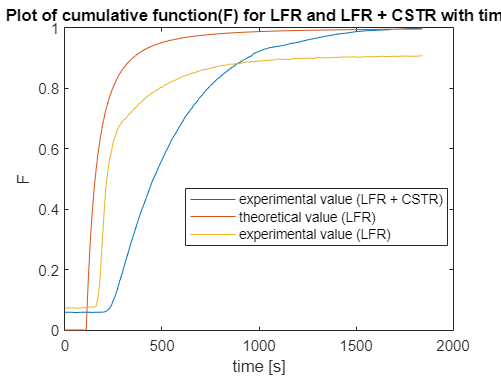


% Plotting F theo and exp
plot(time_step, F_exp_both)
hold on
plot(time_step, F_theo_L)
plot(time_step, F_exp_L)
hold off
xlabel("time [s]")
ylabel("F")
legend('experimental value (LFR + CSTR)', 'theoretical value (LFR)', 'experimental value (LFR)','Location', 'best')
title("Plot of cumulative function(F) for LFR and LFR + CSTR with time")